## Problem 3


$$\omega^2 = 2\gamma\frac{ M_A+M_B}{M_AM_B}\pm4\gamma\sqrt{(M_A+M_B)^2-4M_AM_B(1-\cos^2(\frac{ak_x}{2})\cos^2(\frac{ak_y}{2}))}$$


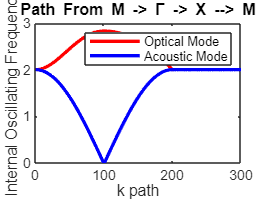

clc
clear
close all

a = 1;
spring = 1;
MA = 1;
MB = 1;

gamma = [0, 0];
M = [pi / a, pi / a];
X = [pi / a, 0];

k_M_GAMMA = [linspace(M(1), gamma(1), 100); linspace(M(2), gamma(2), 100)];
k_GAMMA_X = [linspace(gamma(1), X(1), 100); linspace(gamma(2), X(2), 100)];
k_X_M = [linspace(X(1), M(1), 100); linspace(X(2), M(2), 100)];

w_plus_M_GAMMA = 2 * spring * (MA + MB) / (MA * MB) + (2 * spring / (MA * MB)) * ...
    sqrt((MA + MB)^2 - 4 * MA * MB * (1 - ...
    cos(a * k_M_GAMMA(1,:) /2).^2 .* cos(a * k_M_GAMMA(2,:) / 2).^2));
w_minus_M_GAMMA = 2 * spring * (MA + MB) / (MA * MB) - (2 * spring / (MA * MB)) * ...
    sqrt((MA + MB)^2 - 4 * MA * MB * (1 - ...
    cos(a * k_M_GAMMA(1,:) /2).^2 .* cos(a * k_M_GAMMA(1,:) / 2).^2));

w_plus_GAMMA_X = 2 * spring * (MA + MB) / (MA * MB) + (2 * spring / (MA * MB)) * ...
    sqrt((MA + MB)^2 - 4 * MA * MB * (1 - ...
    cos(a * k_GAMMA_X(1,:) /2).^2 .* cos(a * k_GAMMA_X(2,:) / 2).^2));
w_minus_GAMMA_X = 2 * spring * (MA + MB) / (MA * MB) - (2 * spring / (MA * MB)) * ...
    sqrt((MA + MB)^2 - 4 * MA * MB * (1 - ...
    cos(a * k_GAMMA_X(1,:) /2).^2 .* cos(a * k_GAMMA_X(1,:) / 2).^2));

w_plus_X_M = 2 * spring * (MA + MB) / (MA * MB) + (2 * spring / (MA * MB)) * ...
    sqrt((MA + MB)^2 - 4 * MA * MB * (1 - ...
    cos(a * k_X_M(1,:) /2).^2 .* cos(a * k_X_M(2,:) / 2).^2));
w_minus_X_M = 2 * spring * (MA + MB) / (MA * MB) - (2 * spring / (MA * MB)) * ...
    sqrt((MA + MB)^2 - 4 * MA * MB * (1 - ...
    cos(a * k_X_M(1,:) /2).^2 .* cos(a * k_X_M(1,:) / 2).^2));

omega_plus = [sqrt(w_plus_M_GAMMA) sqrt(w_plus_GAMMA_X) sqrt(w_plus_X_M)];
omega_minus = [sqrt(w_minus_M_GAMMA) sqrt(w_minus_GAMMA_X) sqrt(w_minus_X_M)];

figure;
plot(omega_plus, 'r', 'LineWidth', 2);
hold on;
plot(omega_minus, 'b', 'LineWidth', 2);
legend('Optical Mode', 'Acoustic Mode');
ylabel('Internal Oscillating Frequency');
xlabel('k path')
title('Path From M -> \Gamma -> X --> M');